# **第四章**

4.32 已知两个序列分别为


$${\;\;\;\;\;\;\;\;\;\;\;\;\;\;x}_1 {\left(n\right)}={\left\{\begin{array}{c}
2,1,1,2\ \ \ \ \ n=0,1,2,3\\
0,\ \ \ \ \ \ \ 其他
\end{array}\right)}$$



$${\;\;\;\;\;\;\;\;\;\;\;\;\;\;x}_2 {\left(n\right)}={\left\{\begin{array}{c}
1,-1,-1,1,\ \ \ n=0,1,2,3\\
0,\ \ \ \ \ \ 其他
\end{array}\right)}$$


- 直接在时域计算${\mathrm{x}}_1 {\left(n\right)}$与${\mathrm{x}}_2 {\left(n\right)}$的4点循环卷积。

- 利用matlab，采用离散傅里叶变换计算出${\mathrm{x}}_1 {\left(n\right)}$与${\mathrm{x}}_2 {\left(n\right)}$的4点循环卷积。验证离散傅里叶变换的时域循环卷积定理。

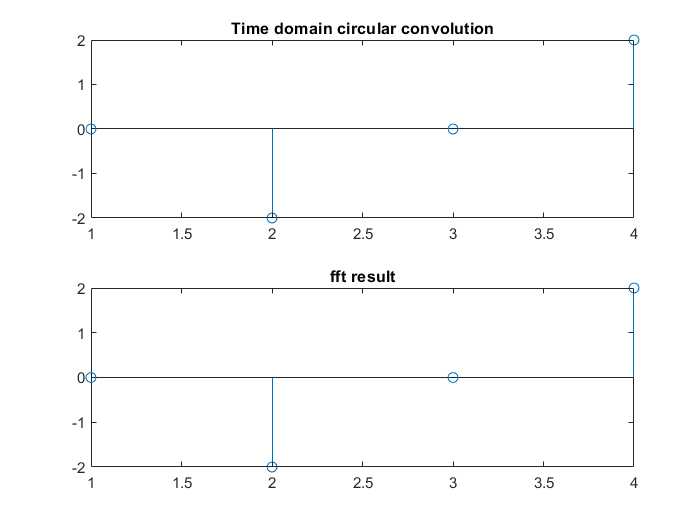

x1=[2 1 1 2];
x2=[1 -1 -1 1];
x3=cconv(x1,x2,4);
figure(1)
subplot(2,1,1);
stem(x3);
title('Time domain circular convolution');
f1=fft(x1);
f2=fft(x2);
f3=f1.*f2;
x3=ifft(f3);
subplot(2,1,2);
stem(x3);
title('fft result');

4.33 已知序列$\mathrm{h}{\left(\mathrm{n}\right)}={\mathrm{R}}_4 {\left(n\right)},x{\left(n\right)}=nR_4 \left(n\right)$。利用matlab实现下列各式的计算。

(1) ${\mathrm{y}}_{\mathrm{f}} {\left(n\right)}=h{\left(n\right)}*x{\left(n\right)};$

(2) 4点循环循环卷积${\mathrm{y}}_{\mathrm{c}} {\left(n\right)}=h{\left(n\right)}\textrm{⊛}x{\left(n\right)};$

(3) 7 点循环卷积${\mathrm{y}}_{\mathrm{c}} {\left(n\right)}=h{\left(n\right)}\textrm{⊛}x{\left(n\right)};$

(4) 8 点循环卷积${\mathrm{y}}_{\mathrm{c}} {\left(n\right)}=h{\left(n\right)}\textrm{⊛}x{\left(n\right)};$

从而说明用离散傅里叶变换的循环卷积计算线性卷积的方法。

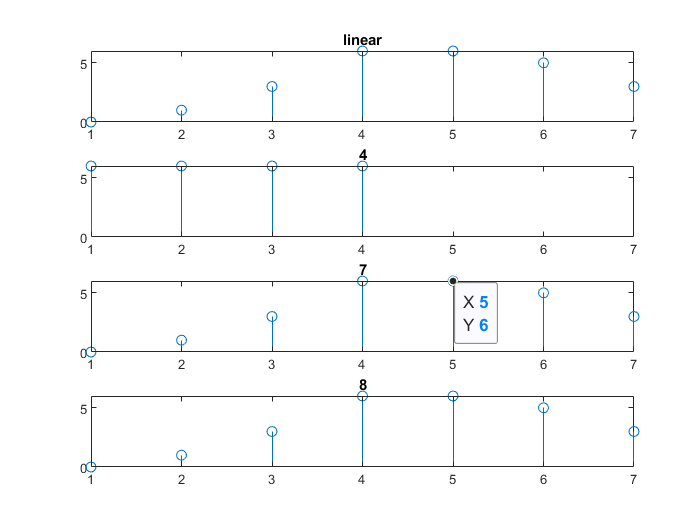

h1=ones(4,1);x1=zeros(4,1);
for i = 0:3
    x1(i+1)=i*h1(i+1);
end
yf=conv(h1,x1);
yc1=cconv(h1,x1,4);
yc2=cconv(h1,x1,7);
yc3=cconv(h1,x1,8);
figure(2)
ax1=subplot(4,1,1);
stem(yf);title('linear');
ax2=subplot(4,1,2);
stem(yc1);title('4');
ax3=subplot(4,1,3);
stem(yc2);title('7');
ax4=subplot(4,1,4);
stem(yc3);title('8');
linkaxes([ax1 ax2 ax3 ax4])

4.35 已知序列$\mathrm{x}{\left(\mathrm{n}\right)}=\cos {\left(\omega_0 n\right)}+0.75\cos {\left(\omega_1 n\right)}\ \ \ {\left(o\le n\le 63\right)},$其中，$\omega_0 =\frac{2\pi }{15}rad\ ,\omega_1 =\frac{2.3\pi }{15}rad$。编写matlab谱分析程序，完成：

（1） 对做64点离散傅里叶变换，画出信号的幅频特性曲线。

（2） 如果（1）中显示的信号谱线不能分辨两个信号分量的谱峰，是否可通过对信号末端补零，再对补零后的序列做大于64点的离散傅里叶变换而分辨出两个谱峰。请通过编程计算来证实，并解释其原因。

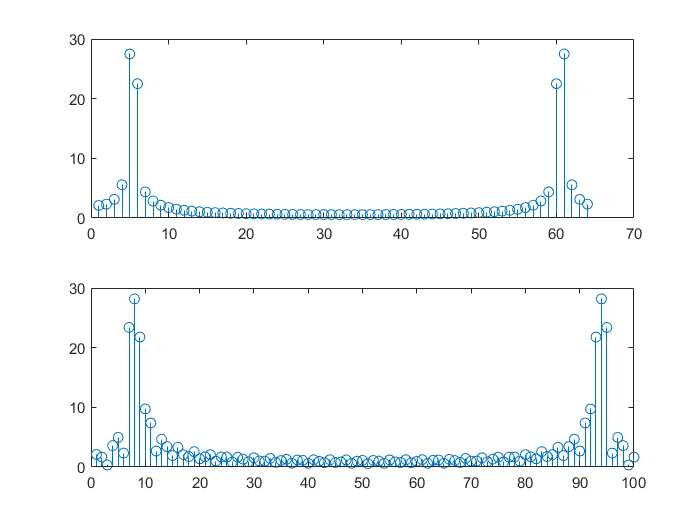

x1=zeros(64,1);
w0=2*pi./15;
w1=2.3*pi./15;
for i =1:64
    x1(i)=cos(w0.*(i-1))+0.75*cos(w1.*(i-1));
end
f1=fft(x1,64);
figure(3)
subplot(2,1,1)
stem(abs(f1));
subplot(2,1,2)
stem(abs(fft(x1,100)));

4.36 已知连续时间信号${\mathrm{x}}_{\mathrm{a}} {\left(t\right)}=e^{-3t} u{\left(t\right)}$，试利用离散傅里叶变换对其进行近似谱分析。要求频率分辨率为1Hz，确定采样频率${\mathrm{f}}_{\mathrm{a}}$，采样点数N以及所需要的信号持续时间${\mathrm{T}}_{\mathrm{p}}$。编写matlab程序完成信号的谱分析。

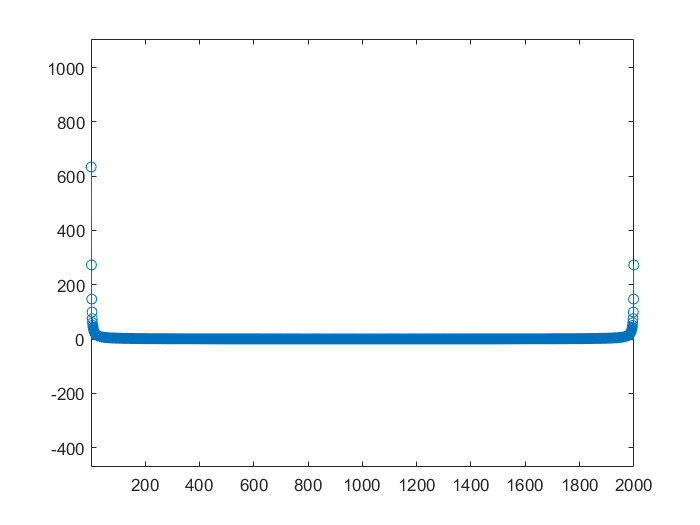

fc=1000;%
fp=1;%
fs=2*fc;%
Tp=1;%
N=2*fc/fp;%
xs=zeros(N,1);
for i=0:N-1
    xs(i+1)=exp(-3*(Tp*(i)/N));
end
f1=fft(xs,N);
figure(4)
stem(abs(f1))
axis equal